## Program for analysing kinematics of multibody systems

Plan of action:

- Generate input data structure based on the example of slider crank

- Generate constraints and it derivatives (e.g., Newton-Raphson requires constraint vector and it's Jacobian).

- Solve system using NR and advance in time. Store data.

- After solution, make some ilustrative plots.

### Example: slider crank

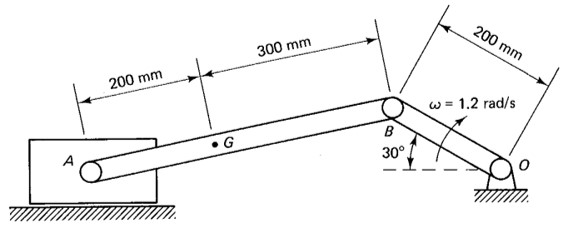

Body numbering

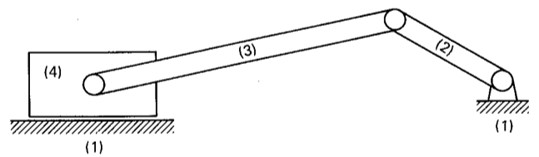

Local coordinate frames

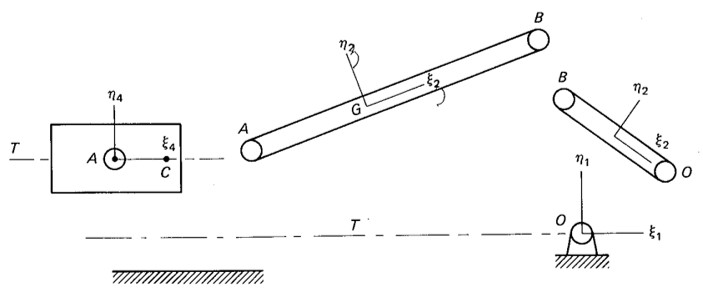

Data from the user

- Bodies and their coordinate frames.

- Joints and their characteristic points

- Solver settings

### Bodies and coordinates

mbs = init_mbs();
mbs = add_body(mbs, "ground");
mbs = add_body(mbs, "crank", -0.1, 0.1, -deg2rad(30));
mbs = add_body(mbs, "link", -0.45, 0.1, deg2rad(15));
mbs = add_body(mbs, "slider", -0.6)

mbs = struct with fields:
     bodies: [1×4 struct]
     joints: [1×1 struct]
         nq: 12
         nc: 0
    gravity: []
     forces: [1×1 struct]
     balpha: 5
      bbeta: 5


### Joints and characteristic points

Vectors that points to joint locations are in local coordinate frame. They do not change locations in time.

mbs = add_revolute(mbs, "revO", "ground", [0; 0], "crank", [0.1, 0.0]);
mbs = add_revolute(mbs, "revB", "crank", [-0.1; 0], "link", [0.3, 0.0]);
mbs = add_revolute(mbs, "revA", "link", [-0.2; 0], "slider", [0.0, 0.0]);

% Simple joints
mbs = add_simple_joint(mbs, "groundx", "ground", "x", 0);
mbs = add_simple_joint(mbs, "groundy", "ground", "y", 0);
mbs = add_simple_joint(mbs, "groundangle", "ground", "fi", 0);

mbs = add_simple_joint(mbs, "slidertranslation", "slider", "y", 0);
mbs = add_simple_joint(mbs, "sliderrotation", "slider", "fi", 0);

% Driving constraint for the crank
om = 1.2; % rad/s
mbs = add_driving_joint(mbs, "crankrotation", "crank", "fi", @(t)-deg2rad(30) - om * t);

### Basic checking

fprintf("System has %d bodies and %d coordinates.\n", length(mbs.bodies), mbs.nq)

System has 4 bodies and 12 coordinates.


fprintf("Number of the joints:\n\tRevolute: %d\n\tPrismatic: %d\n", ...
    length(mbs.joints.revolute), length(mbs.joints.prismatic))

Number of the joints:
	Revolute: 3
	Prismatic: 0


fprintf("\tSimple: %d\n\tDriving: %d\n", length(mbs.joints.simple), length(mbs.joints.driving))

	Simple: 5
	Driving: 1


fprintf("In total %d DOF are constrained!\n", mbs.nc)

In total 12 DOF are constrained!


### **Coordinates (initial values)**

They vere defined in the mbs.bodies. We want to put them together in single vector.

q0 = initial_position(mbs);

### Constraints vector C

t0 = 0.0;
C = constraints(mbs, q0, t0);

### Solution using fsolve

Now we can check the code with function fsolve

tic
q0_correct = fsolve(@(y)constraints(mbs, y, 0.0), q0);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


toc

Elapsed time is 0.061706 seconds.


% disp([q0, q0_correct])
C0 = constraints(mbs, q0_correct, t0)

C0 = 	1.0e+-7 *

         0
         0
    0.3009
    0.0613
    0.2006
    0.0409
         0
         0
         0
         0


### Jacobian of constraints

We need it for position and velocity analysis (and we will need it for euqations of motion).

Cq = constraints_dq(mbs, q0);

Now we can solve kinematic analysis on position (initial) using Newton-Raphson

tic
[q0_correct_NR, NR_iter] = ...
    NR_method(@(y)constraints(mbs, y, 0.0), ...
    @(y)constraints_dq(mbs, y), q0, 1e-8)

q0_correct_NR =          0
         0
         0
   -0.0866
    0.0500
   -0.5236
   -0.4671
    0.0400
    0.2014
   -0.6631


NR_iter = 3

toc

Elapsed time is 0.050006 seconds.


Simple check

disp([q0, q0_correct, q0_correct_NR])

         0         0         0
         0         0         0
         0         0         0
   -0.1000   -0.0866   -0.0866
    0.1000    0.0500    0.0500
   -0.5236   -0.5236   -0.5236
   -0.4500   -0.4671   -0.4671
    0.1000    0.0400    0.0400
    0.2618    0.2014    0.2014
   -0.6000   -0.6631   -0.6631
         0         0         0
         0         0         0



C0_NR = constraints(mbs, q0_correct_NR, t0)

C0_NR = 	1.0e+-16 *

         0
         0
    0.5551
    0.1388
         0
    0.1388
         0
         0
         0
         0


### Kinematic analysis on position

h = 0.05;
t_end = 1;
tol = 1e-8;
[T, Q, Qp, niter] = kinematic_analysis(mbs, q0, h, t_end, tol)

T =          0    0.0500    0.1000    0.1500    0.2000    0.2500    0.3000    0.3500    0.4000    0.4500    0.5000    0.5500    0.6000    0.6500    0.7000    0.7500    0.8000    0.8500    0.9000    0.9500    1.0000


Q =          0         0         0   -0.0866    0.0500   -0.5236   -0.4671    0.0400    0.2014   -0.6631         0         0
         0         0         0   -0.0834    0.0551   -0.5836   -0.4595    0.0441    0.2222   -0.6546         0         0
         0         0         0   -0.0800    0.0600   -0.6436   -0.4512    0.0480    0.2424   -0.6454         0         0
         0         0         0   -0.0763    0.0647   -0.7036   -0.4423    0.0518    0.2618   -0.6355         0         0
         0         0         0   -0.0722    0.0692   -0.7636   -0.4328    0.0553    0.2803   -0.6250         0         0
         0         0         0   -0.0680    0.0734   -0.8236   -0.4227    0.0587    0.2978   -0.6139         0         0
         0         0         0   -0.0634    0.0773   -0.8836   -0.4122    0.0618    0.3144   -0.6024         0         0
         0         0         0   -0.0587    0.0810   -0.9436   -0.4012    0.0648    0.3298   -0.5904         0         0
         0         0        

Qp =          0         0         0    0.0600    0.1039   -1.2000    0.1455    0.0831    0.4243    0.1624         0         0
         0         0         0    0.0661    0.1001   -1.2000    0.1594    0.0801    0.4107    0.1775         0         0
         0         0         0    0.0720    0.0960   -1.2000    0.1725    0.0768    0.3955    0.1915         0         0
         0         0         0    0.0776    0.0915   -1.2000    0.1847    0.0732    0.3789    0.2043         0         0
         0         0         0    0.0830    0.0867   -1.2000    0.1959    0.0693    0.3608    0.2159         0         0
         0         0         0    0.0880    0.0816   -1.2000    0.2061    0.0652    0.3412    0.2261         0         0
         0         0         0    0.0928    0.0761   -1.2000    0.2152    0.0609    0.3202    0.2350         0         0
         0         0         0    0.0972    0.0704   -1.2000    0.2233    0.0563    0.2977    0.2425         0         0
         0         0       

niter =      3     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


Very basic postprocessing

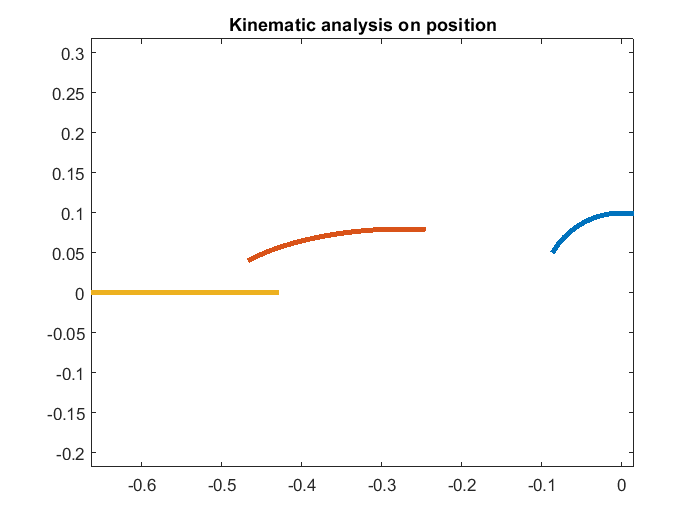

plot(Q(:, 4), Q(:, 5), Q(:, 7), Q(:, 8), ...
    Q(:, 10), Q(:, 11), 'LineWidth', 3)
axis equal
title('Kinematic analysis on position')

Now similar plot for velocity

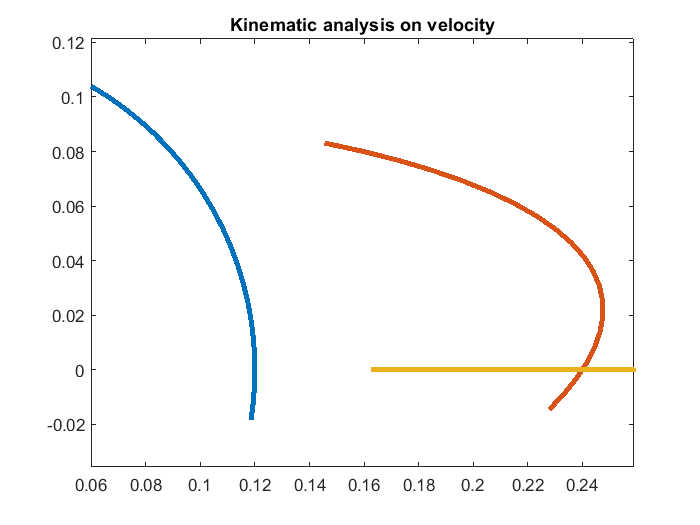

plot(Qp(:, 4), Qp(:, 5), Qp(:, 7), Qp(:, 8), ...
    Qp(:, 10), Qp(:, 11), 'LineWidth', 3)
axis equal
title('Kinematic analysis on velocity')

Number of NR iterations

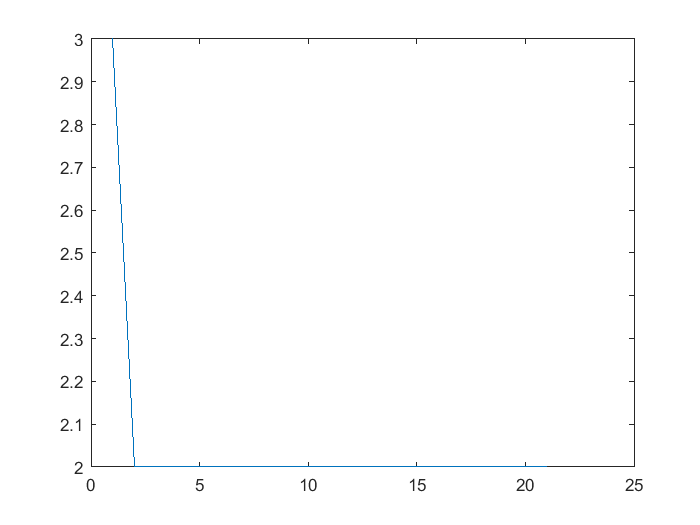

plot(niter)